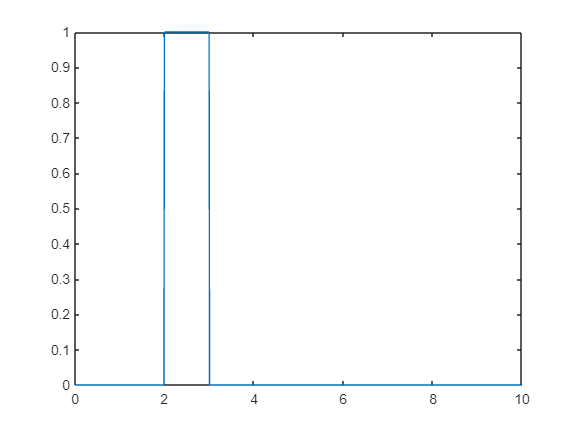

clear all, close all, clc

t1 = 0:0.01:10;
t2 = 0:0.01:20;
u =@(t) ((t<=3)&(t>=2));

plot(t1,u(t1))

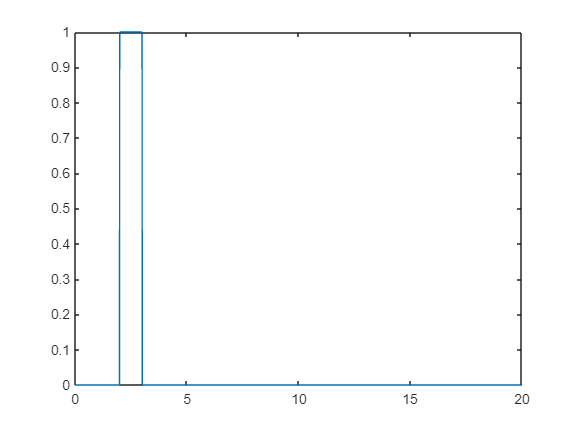

plot(t2,u(t2))

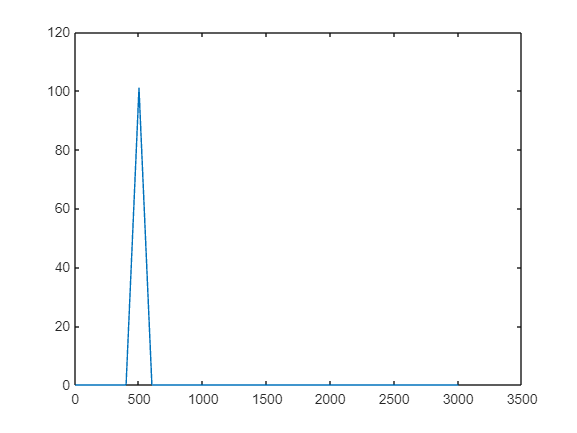

y = conv(u(t1),u(t2),"full");
plot(y)

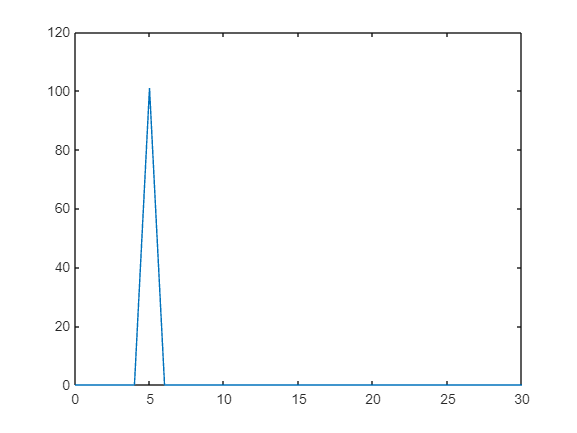


t3 = t1(1)+t2(1):0.01:t1(length(t1))+t2(length(t2));
plot(t3,y)

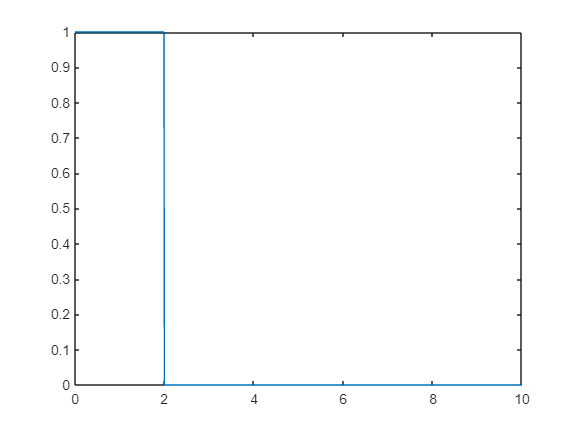


%Señal x(t)
a = 2;
b = 6;
u2 = @(t) (t>=0);
x =@(t) u2(t)-u2(t-a);
plot(t1,x(t1))

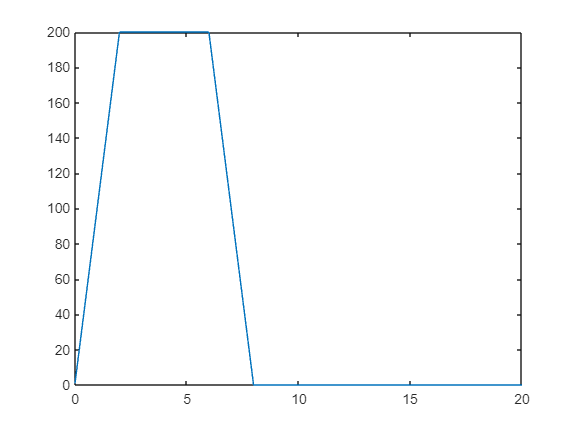

h = @(t) u2(t)-u2(t-b);
y = conv(x(t1),h(t1),"full");
tconv = 0:0.01:20;
plot(tconv,y)

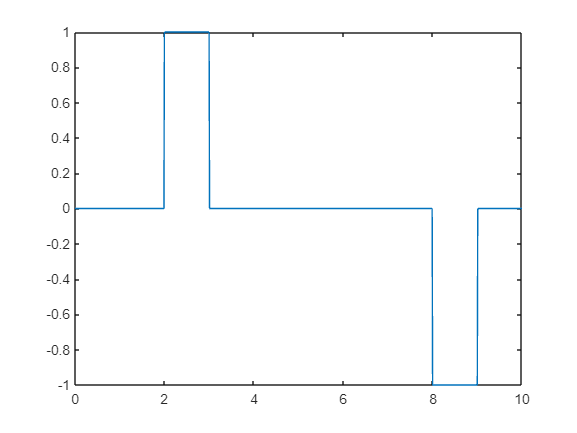


%señal h(t)
h =@(t) u(t)-u(t-b);
plot(t1,h(t1))

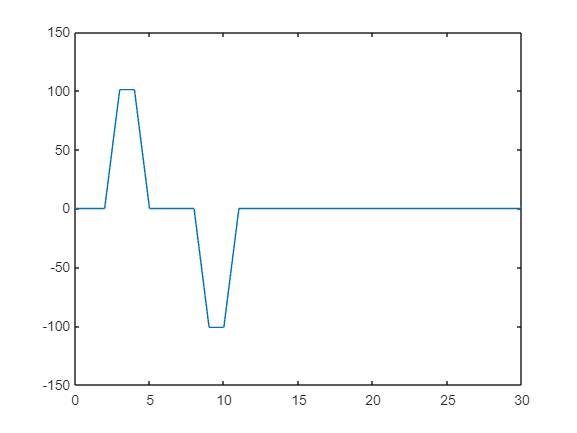


%Convolucion
y = conv(x(t1),h(t2),"full");

plot(t3,y)